Computational Intelligence Course, AUTH

Author: Tzouvaras Evangelos

AEM: 9659

email: tzouevan@ece.auth.gr

Description:

This livescript contains the code and the output results for the PI controller that controls the angle of a satelite. 

Root Locus analysis for the open loop transfer function:

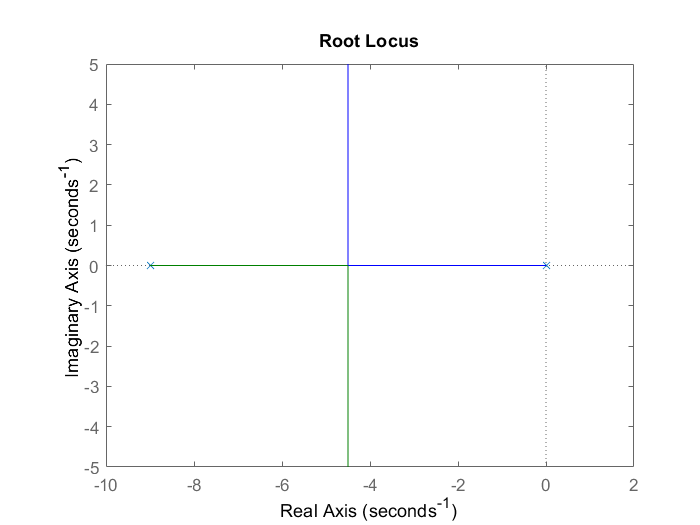

% Root Locus analysis for the open loop transfer function. Parameter kp
% will be ingored

% Open loop transfer function (without the kp parameter)
A_s = tf([10],[1 9 0]);
rlocus(A_s);

Step response for the closed loop transfer function, after the calculation of the gain:

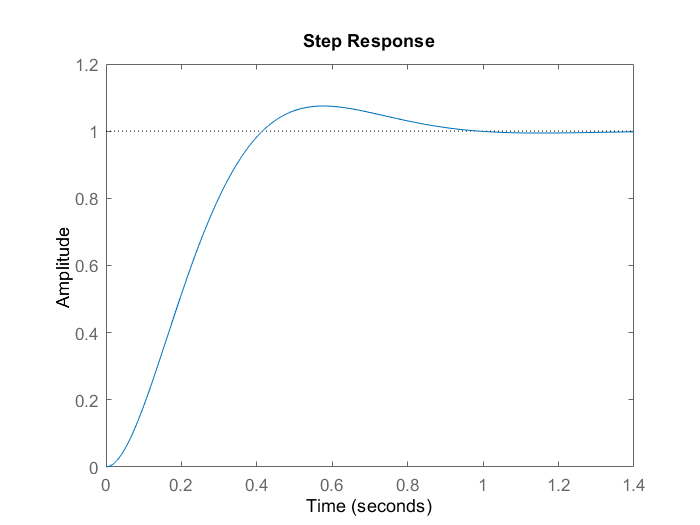

% Open loop transfer function for kp = 5
A_s = tf([50],[1 9 0]);

% Closed loop transfer function for kp = 5
H_s = feedback(A_s, 1, -1);

% Step response for the closed loop transfer function
figure;
step(H_s);


% Info about the step response
S = stepinfo(H_s);

% Print the results about rise time and overshoot 
fprintf('STEP RESPONSE RESULTS');

STEP RESPONSE RESULTS

fprintf('Rise time(sec): %f', S.RiseTime);

Rise time(sec): 0.275290

fprintf('Overshoot(%%): %f', S.Overshoot);

Overshoot(%): 7.486156